# HW03

## Problem 3.

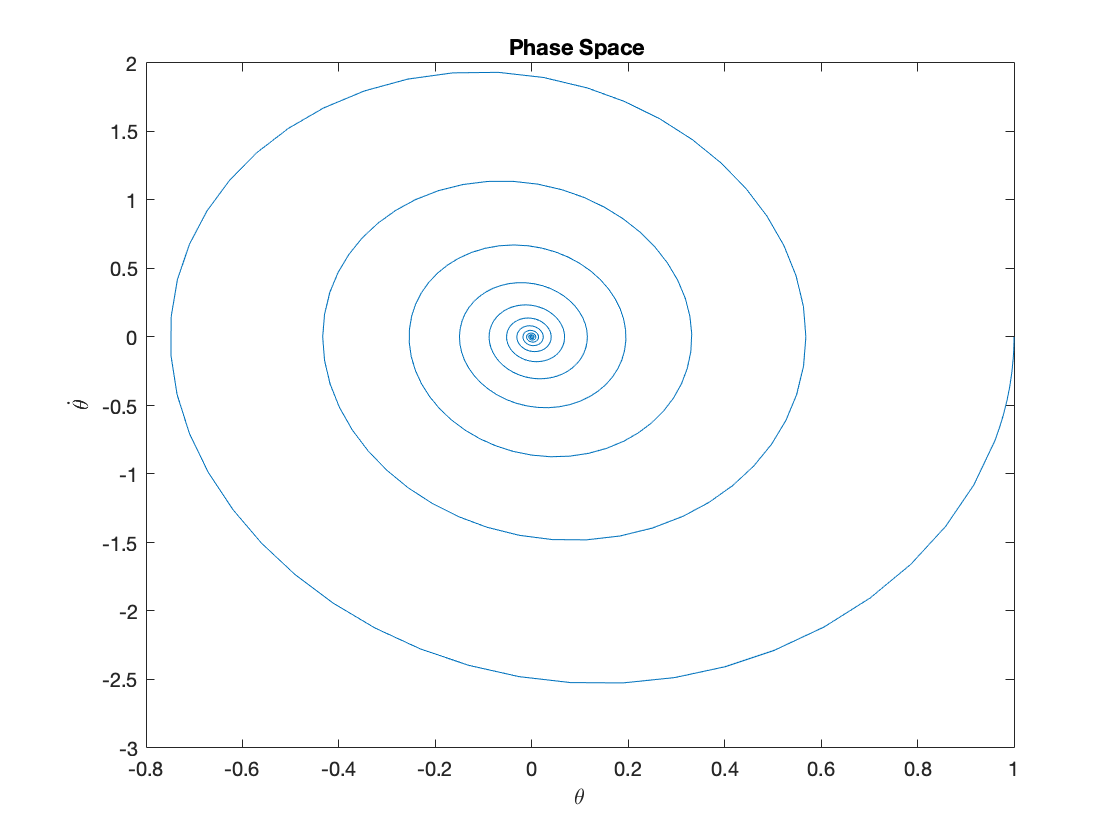

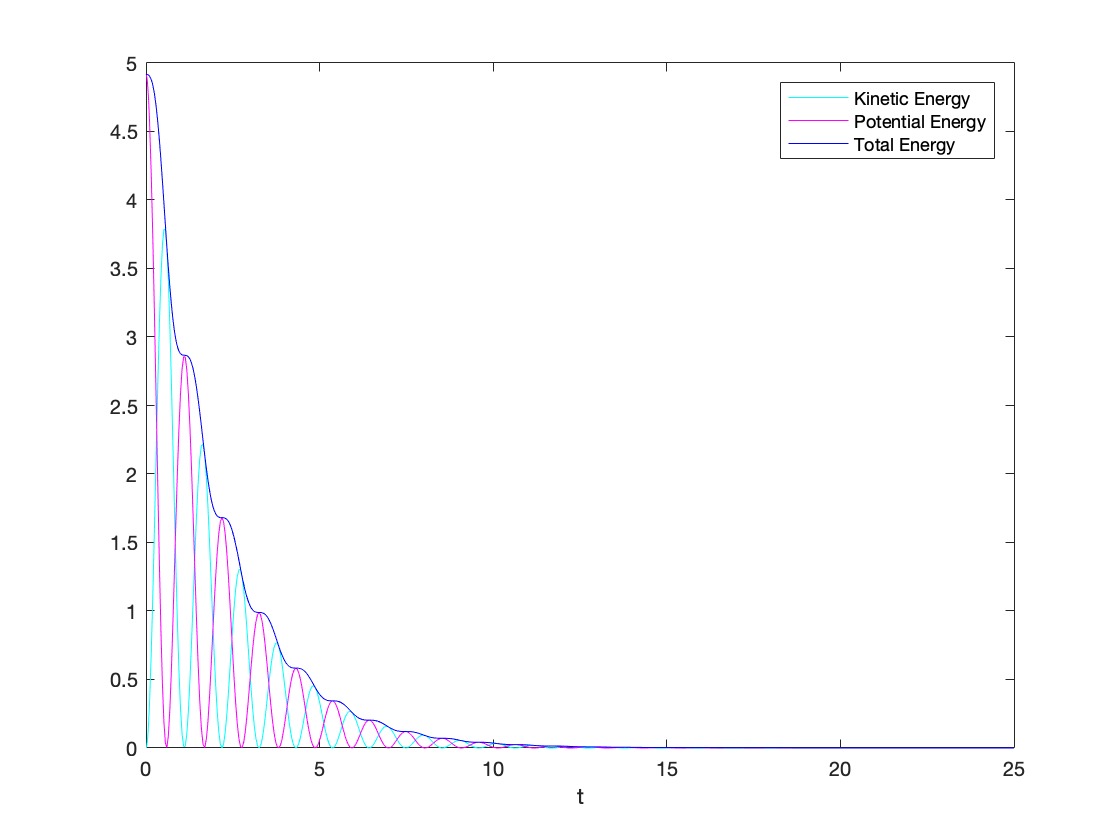

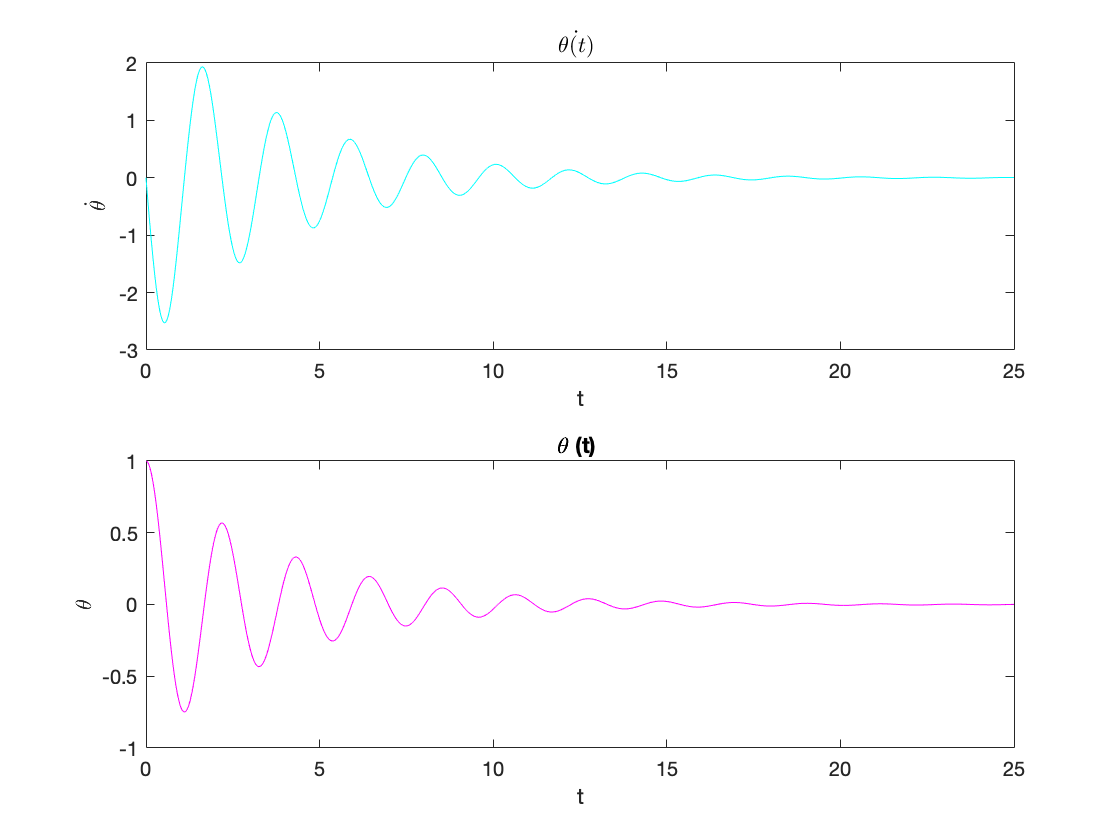

T=damped_pendulum(1.09, 1, 0, 1, 0.5);

T2=pendulum(1.09, 1, 0, 0);
fprintf(' *************************************** \n  damped:   T = %f , w = %f \n  undamped: T = %f , w = %f \n *************************************** \n ', T , 6.28 ./ T , T2, 6.28 ./ T2 );

 *************************************** 
  damped:   T = 2.110693 , w = 2.975326 
  undamped: T = 2.237184 , w = 2.807100 
 *************************************** 
 

## Dependence of angular frequency on damping coefficient :

frequency increases with damping.

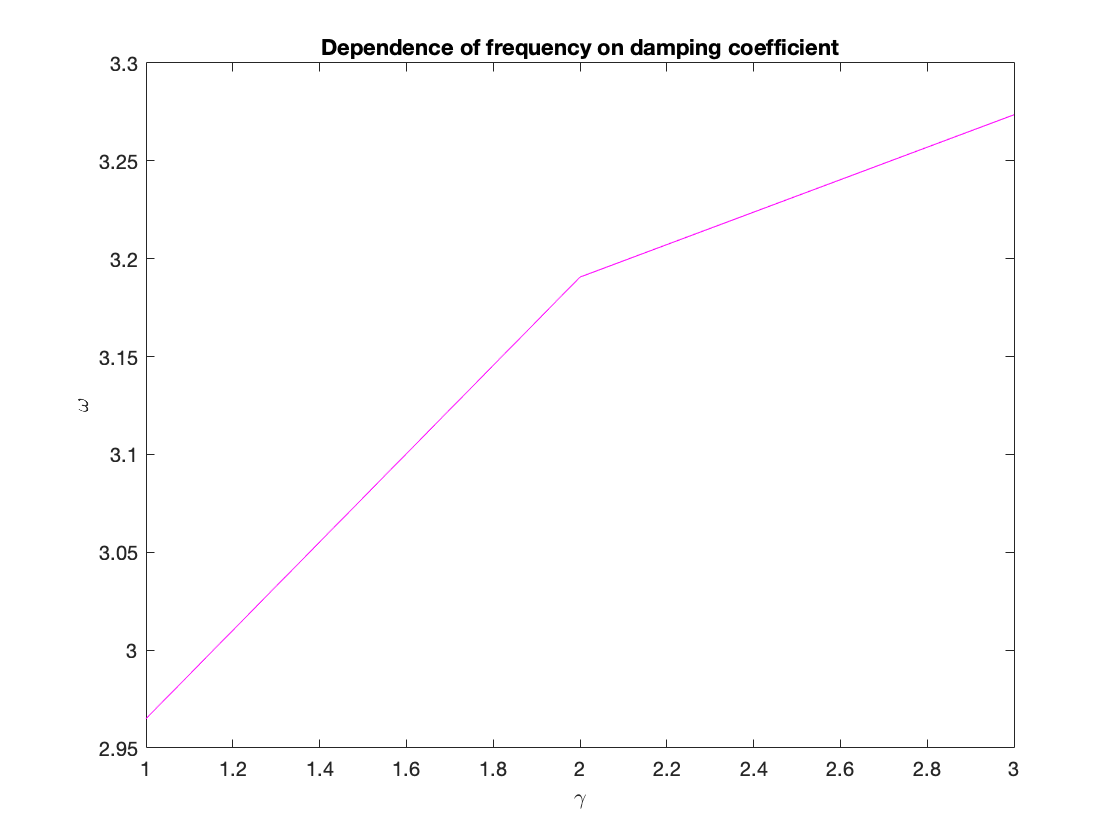

gamma = [ 1, 2, 3];
T=zeros(1,length(gamma));

for i=1:length(gamma)
    T(i)=damped_pendulum(1.09, 1, 0, 0, gamma(i));
end  
w=6.28 ./ T(:);
plot(gamma, w, 'm');
title('Dependence of frequency on damping coefficient')
xlabel('\gamma')
ylabel('\omega')

## Potential Energy and Kinetic Energy : $\gamma =0.5$:

Energies decrease exponentialy.

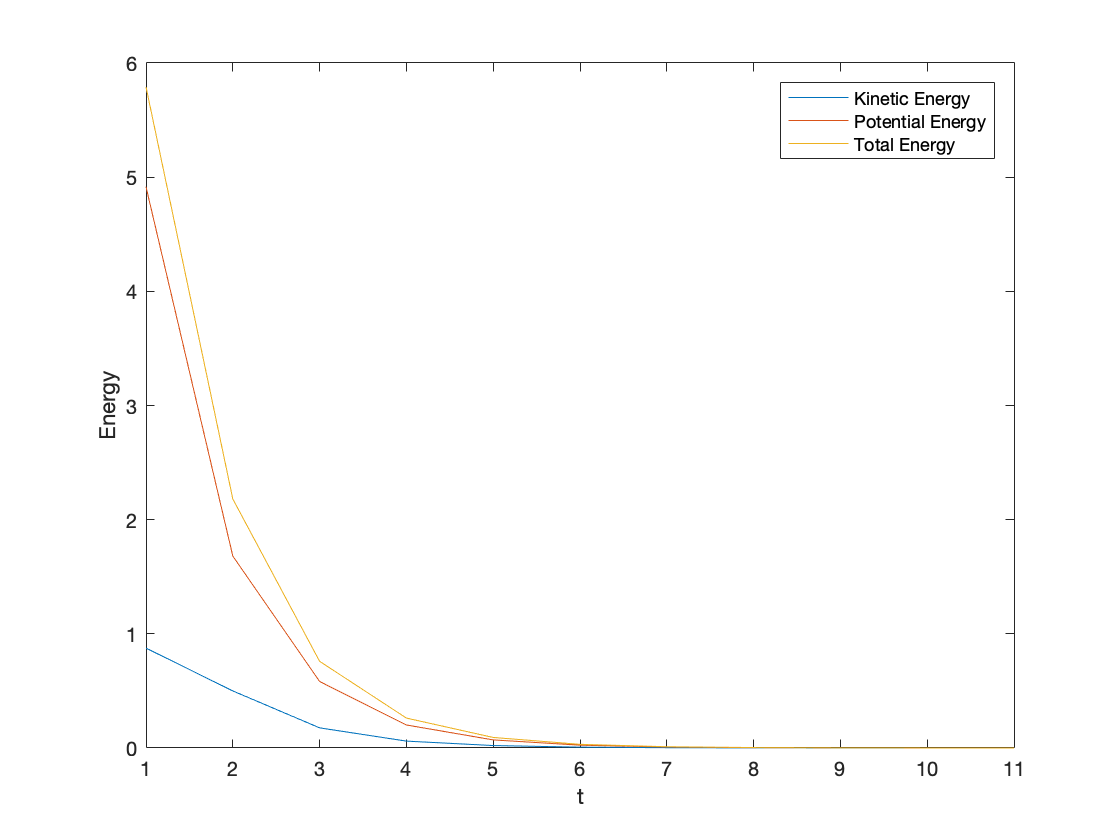

R=1.09;
g= 9.81;

avgKE=[];
avgU=[];
avgE=[];
[T,sol]=damped_pendulum(1.09, 1, 0, 0, 0.5);

ind= find(sol(:,3).*circshift(sol(:,3), [-1 0]) <= 0);
for i =1:(length(ind)-2) / 2 
    n=2 .* i -1;
    KE = 0.5 .* R.^2 .* sol(ind(n): ind(n+2),3).^2;  % Kinetic Energy
    U = g .* R .* (1-cos(sol(ind(n): ind(n),2))) ; % Potential Energy
    E=KE+U; % Total Energy in one cycle
    avgKE=[avgKE,mean(KE)];
    avgU=[avgU,mean(U)];
    avgE=[avgE,mean(E)];
    
end    

n=1:(length(ind)-2) / 2 ;
plot(n,avgKE,n,avgU,n,avgE);
legend('Kinetic Energy', 'Potential Energy','Total Energy')
xlabel('t')
ylabel('Energy')

## Time dependence of $\theta(t)$and $\dot{\theta}(t)$for different damping coefficient:

For $\gamma \geq 5$ the motion is not oscillatory at all and $\theta $ decays only. 

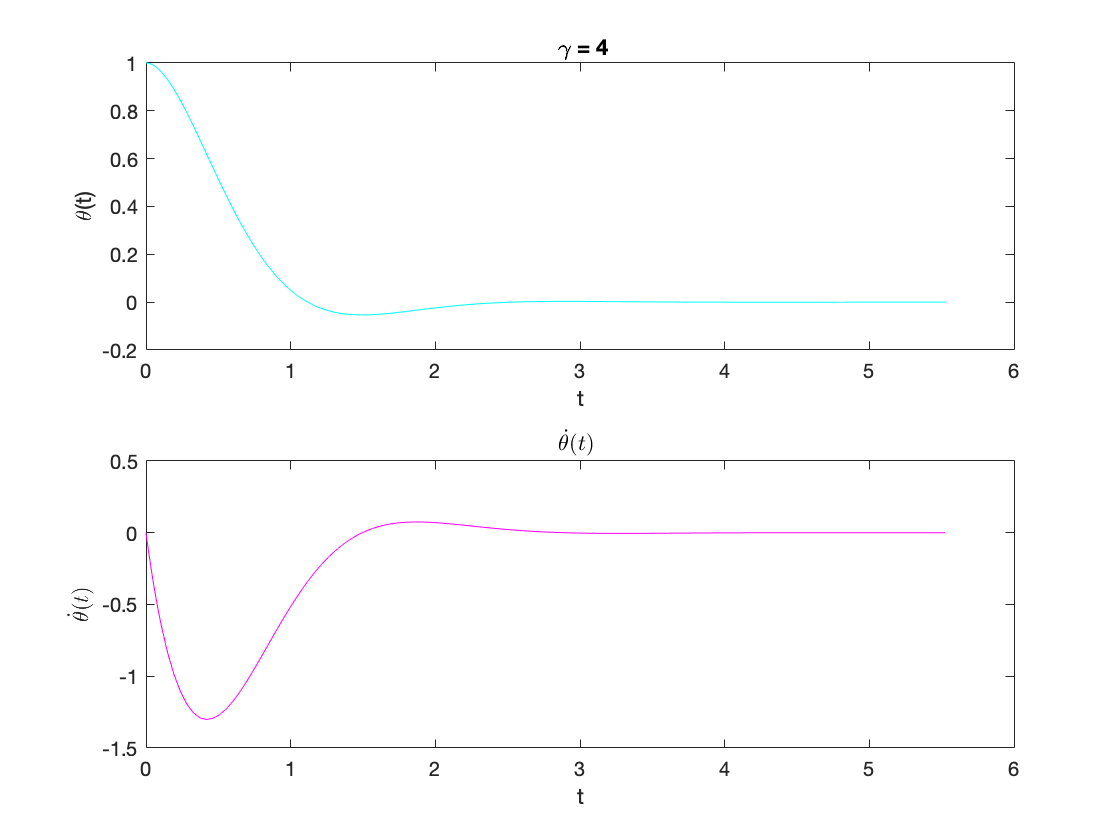

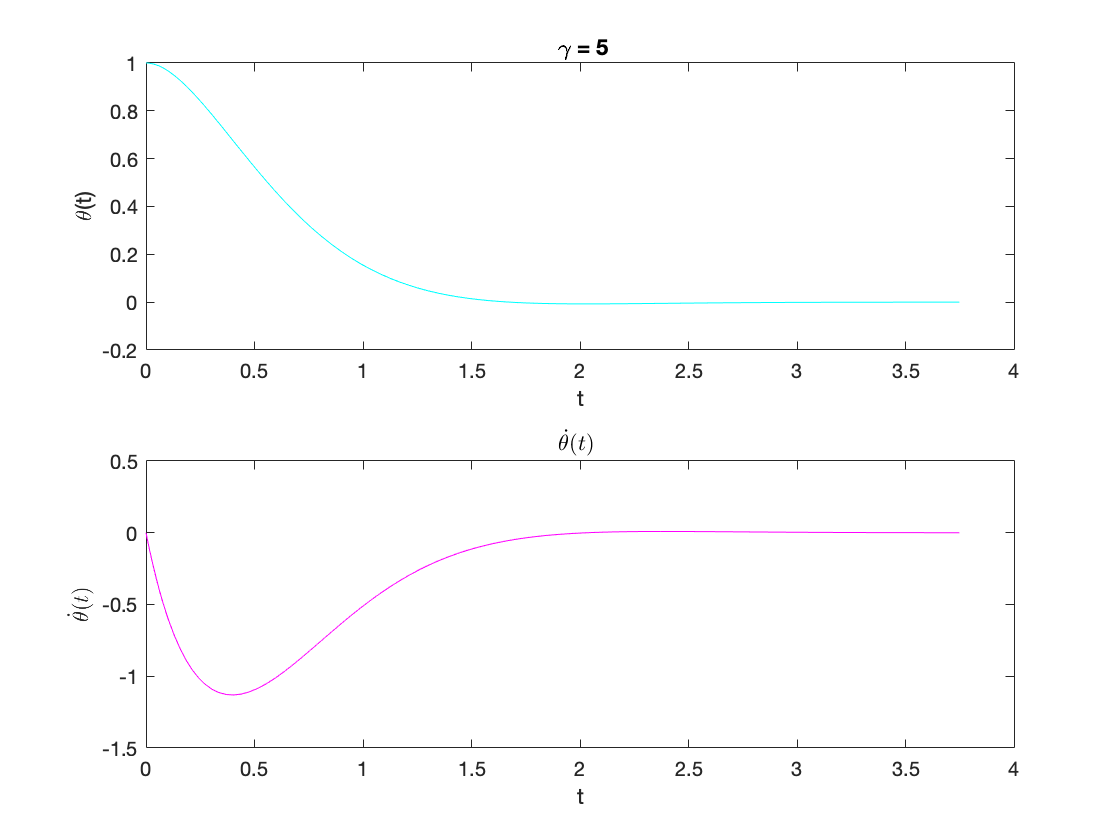

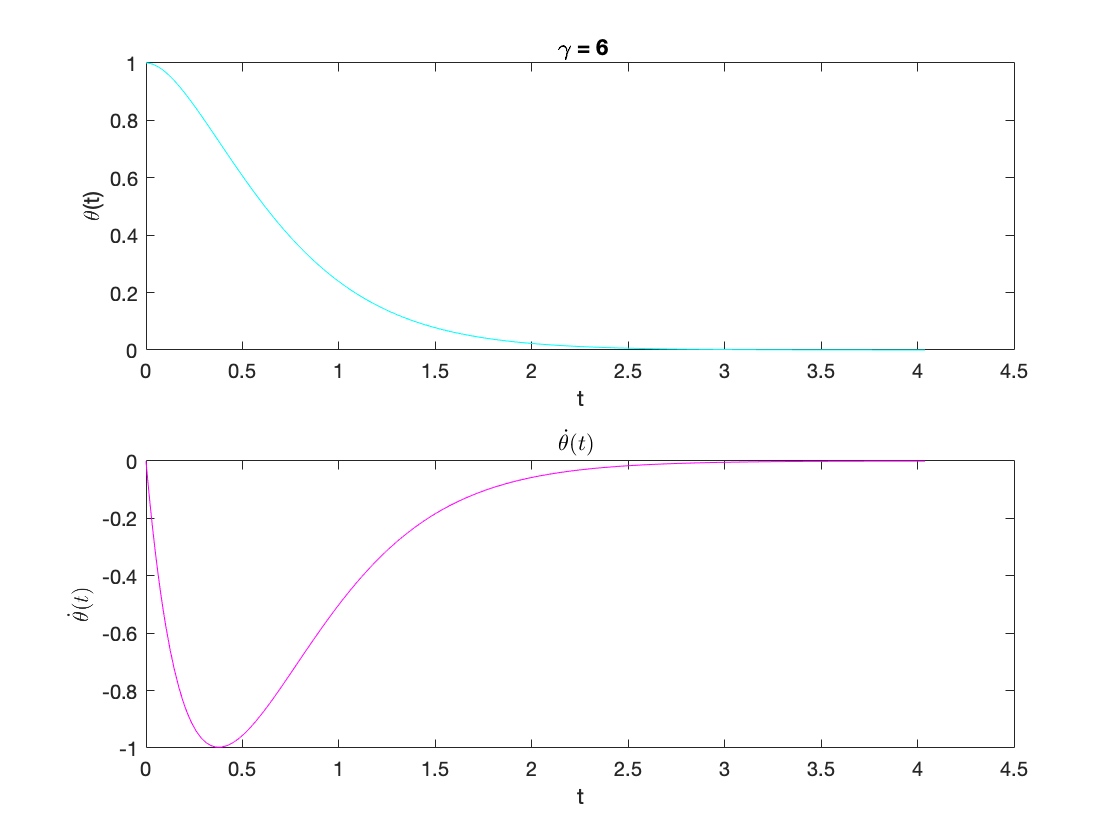

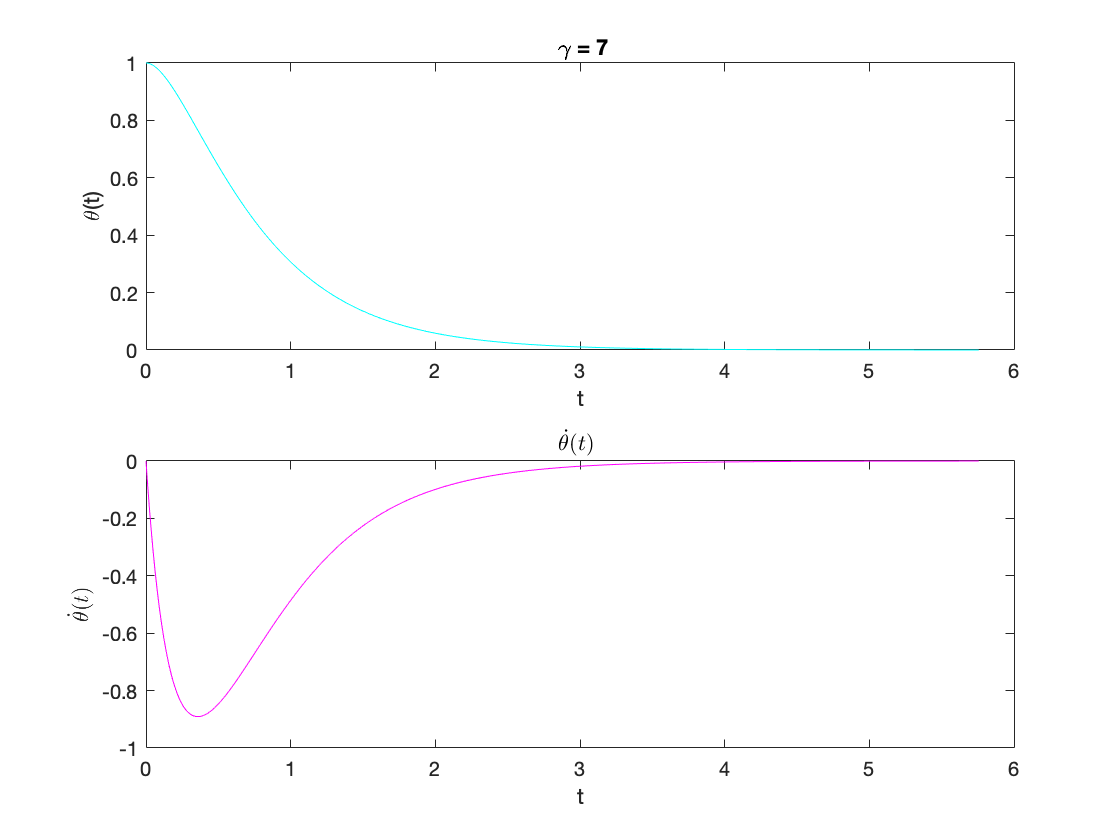

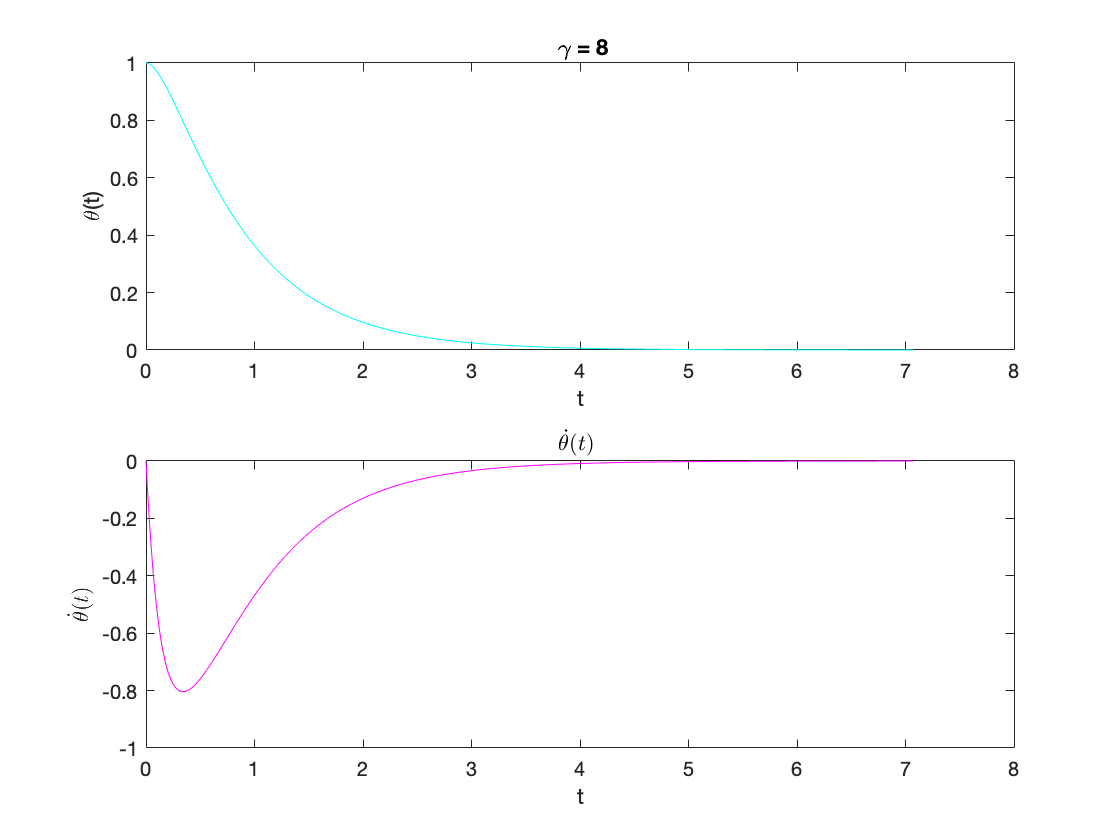

gamma=[4,5,6,7,8];
tf=zeros(1,length(gamma)); % time at which pendulum reaches equilibrium
for i=1:length(gamma)
    
   [T,sol] = damped_pendulum(1.09, 1, 0, 0, gamma(i));
   tf(i)=sol(end,1);
   
   f1=figure ;
    
   subplot(2,1,1);
   plot(sol(:,1),sol(:,2),'c');
   title([' \gamma = ' num2str(gamma(i))])
   xlabel('t')
   ylabel( '\theta(t)')
    
    
   subplot(2,1,2);
   plot(sol(:,1),sol(:,3), 'm');
   title('$\dot{\theta}(t)$ ', 'Interpreter','latex');
   xlabel('t');
   ylabel('$\dot{\theta}(t)$', 'Interpreter','latex');
    
end    

## Equilibrium time :

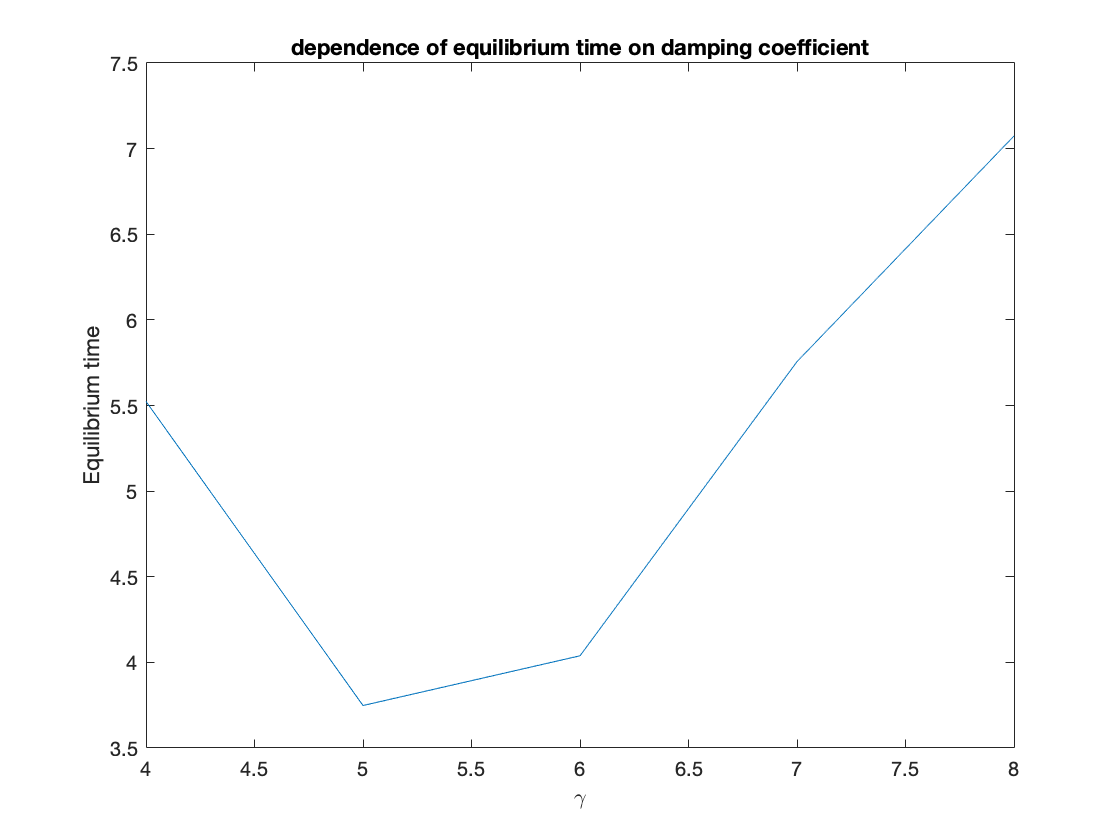

f2=figure;
plot(gamma , tf);
title('dependence of equilibrium time on damping coefficient');
xlabel('\gamma');
ylabel('Equilibrium time');

## Phase diagrams:

For smaller damping coefficient the motion is oscillatory and as a result phase diagrams are spirals but  for larger damping coefficients the velocity starts at zero and increases and to a maximum value and then decreases and reaches to zero at the end due to the large damping. 

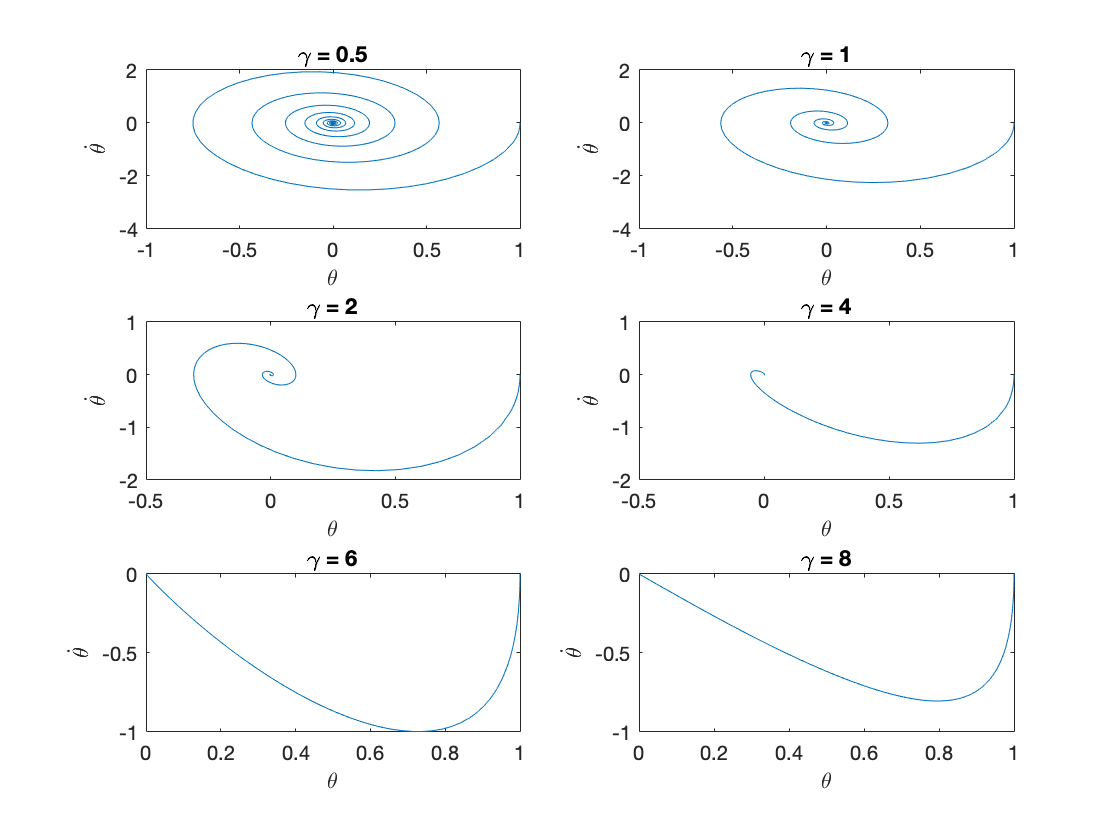

gamma=[0.5,1,2,4,6,8];

for i=1:length(gamma)
    
   [T,sol] = damped_pendulum(1.09, 1, 0, 0, gamma(i));
   
    
    subplot(3,2,i)
    plot(sol(:,2),sol(:,3));
    title(['\gamma = ' num2str(gamma(i))])
    ylabel('$\dot{\theta}$', 'Interpreter','latex')
    xlabel('\theta')
    
end  